# XPLOR demo on Two-Photon Calcium Imaging of a Neuronal Population

Data from I-Wen Chen and Emiliano Ronzitti from Prof. Valentina Emiliani's lab in the Vision Institute.

Thomas Deneux, 17/04/2020

## Load Data

The data consists of 3 movies of 400 frames with 128x128 pixels.

xplor_folder = fileparts(which('xplor'));
cd(xplor_folder)
cd 'demo data'
load neurons_movie
whos

  Name                Size                      Bytes  Class     Attributes

  data              128x128x400x3            19660800  uint8               
  frame_rate          1x1                           8  double              
  pixel_size          1x1                           8  double              
  xplor_folder        1x29                         58  char                



## Start XPLOR and Enter Header Information

Simply type:

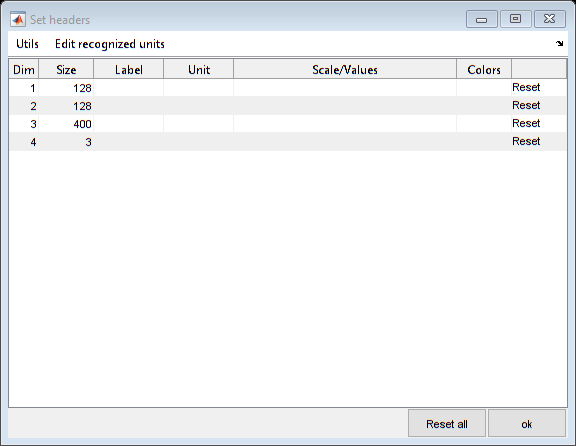

V =   view with properties:

                hf: [1×1 Figure]
            slicer: [1×1 xplr.slicer]
                 C: [1×1 xplr.viewcontrol]
                 D: [1×1 xplr.viewdisplay]
            panels: [1×1 struct]
    controlvisible: 1
              data: [1×1 xplr.xdata]
             slice: [1×1 xplr.xdata]
         listening: [0×0 struct]
       idGraphNode: 0.3897


ans =   xdata with properties:

           data: [20×400×3 single]
         header: [1×3 xplr.dimheader]
           name: ''
             sz: [20 400 3]
             nd: 3
      listening: [0×0 struct]
    idGraphNode: 0.4039


  1x3 xplr.dimheader object with following info:

    label: x-y ROI,time,trial
     type: categorical,measure,categorical
        n: 20,400,3
     unit: ,s,
    dimID: 0.6200
    dimID: 0.1656
    dimID: 0.6020



xplor data

Enter the header information as follows:

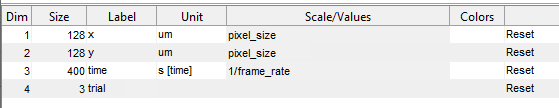

The scale values are interpreted in the base Matlab workspace:

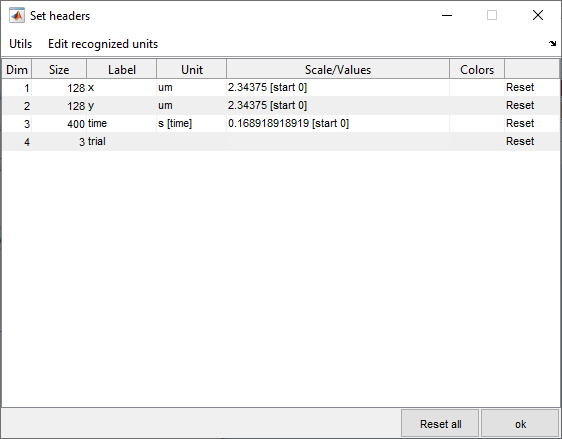

XPLOR will remember these values: you will not need to enter them the next time!

Now press `ok`.

## XPLOR Main Window

The following two windows appear. 

The first is the XPLOR man window, note its control parts on the left (which can be hidden with the `>> Controls` button) and the display on the right. XPLOR chose to show dimensions `x` and `y` in a spatial display, and to filter the other two dimensions: the second window displays lists to control the `time` and `trial` filters.

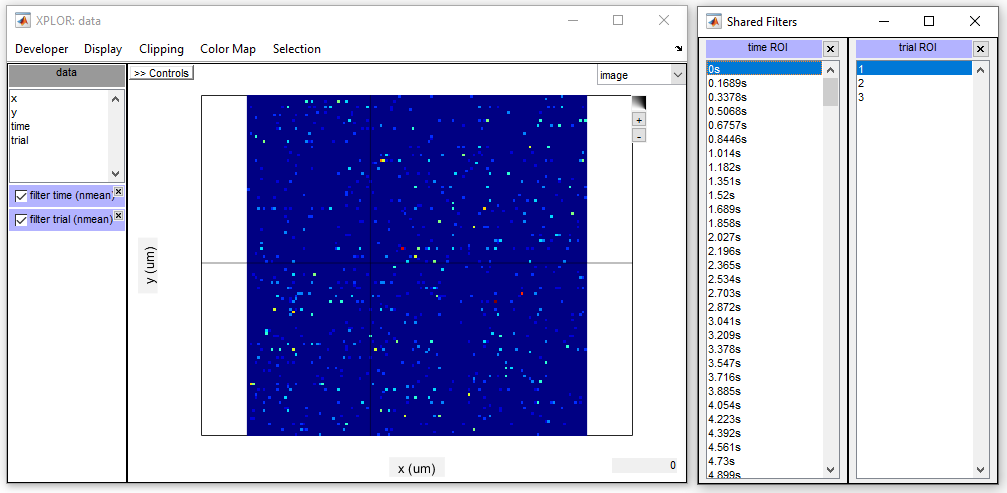

## Linked Windows

In addition to this spatial display, let us show a temporal display from the context menu that appears when clicking `time`.

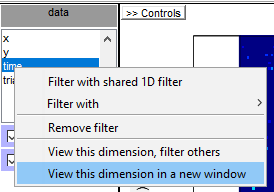

In this new window, `time` is shown, while `x`, `y` and `trial` are filtered (note that `x` and `y` are filtered together by a single 2D filter which we will manipulate soon).

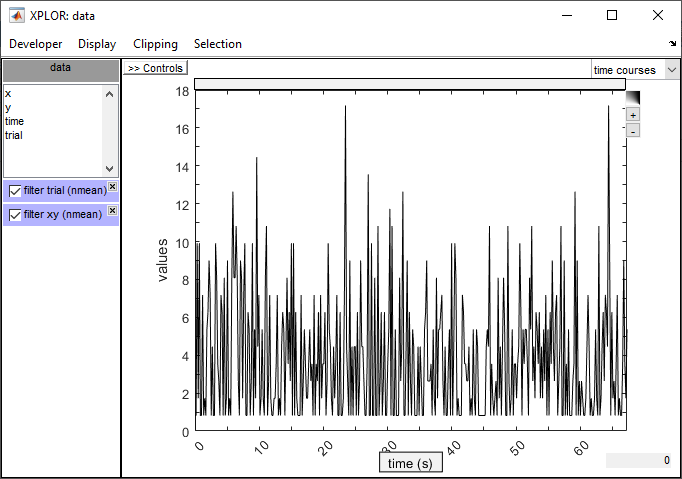

Notice how the two windows are linked together. **Cross-window controls** is a first **core feature** of XPLOR: click any point in the image or drag the cross to see its signal in the time courses display, and reciprocally click any time or drag the vertical cursor in the time courses display to see the frame at that time in the image display.

To avoid saturations, adjust the clipping range: there are many options to control it, here are a few advices:

- Use the `Auto-Clip` feature that automatically adjust the clipping range: it is accessible in the `Clipping` menu but also by by double-clicking on the small black&white button in the top-right corner  . 

- If you want auto-clipping to occur whenever the displayed data changes select in the menu `Span > Local, Adjust to Current View`.

- Clip can be further adjusted by clicking on the black&white button  , holding the button mouse and moving the mouse horizontally to adjust the lower bound, vertically to adjust the upper bounds (their values are displayed bottom-left of the figure). You can also use the + and - minus buttons to adjust the scale  .

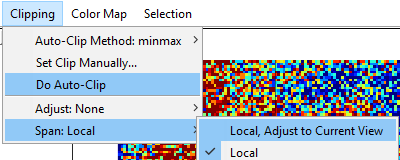

In the screenshot below (note that you can also change the image color map):

- the cross selects a pixel belonging to a neuron -> its signal appears in the second window, we see peaks when the neuron is active

- the vertical bar selects a peak time -> the frame at this time appears in the first window and shows this neuron particularly bright.

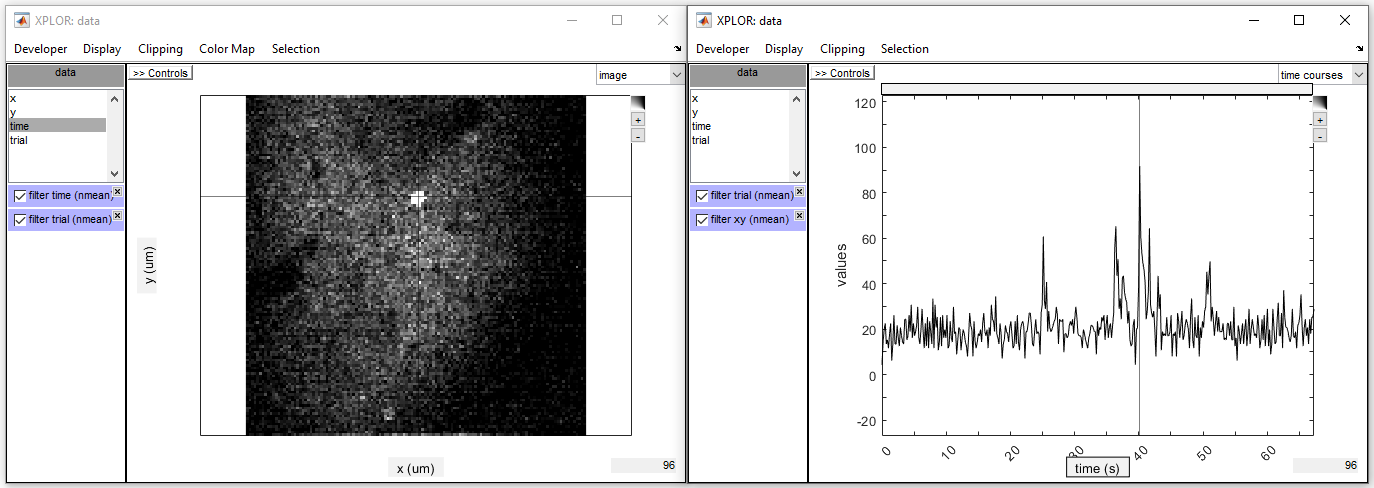

## Regions of Interest, Zooming

In general, XPLOR relies on so-called *filter* objects that define what is being displayed, and we saw how the cross controls so-called *point filters*. Follow now the screenshots to have each window control *selection filters* that define **regions of interest (ROI)** over which to average individual pixels' signals or individual frames.

### 1) Spatial ROI

We want to define in the image display spatial ROIs whose time courses will be shown in the other window

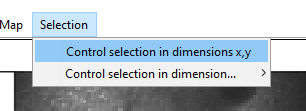

Right-click and drag in the window to make circle selections. Their time courses appear in the second window.

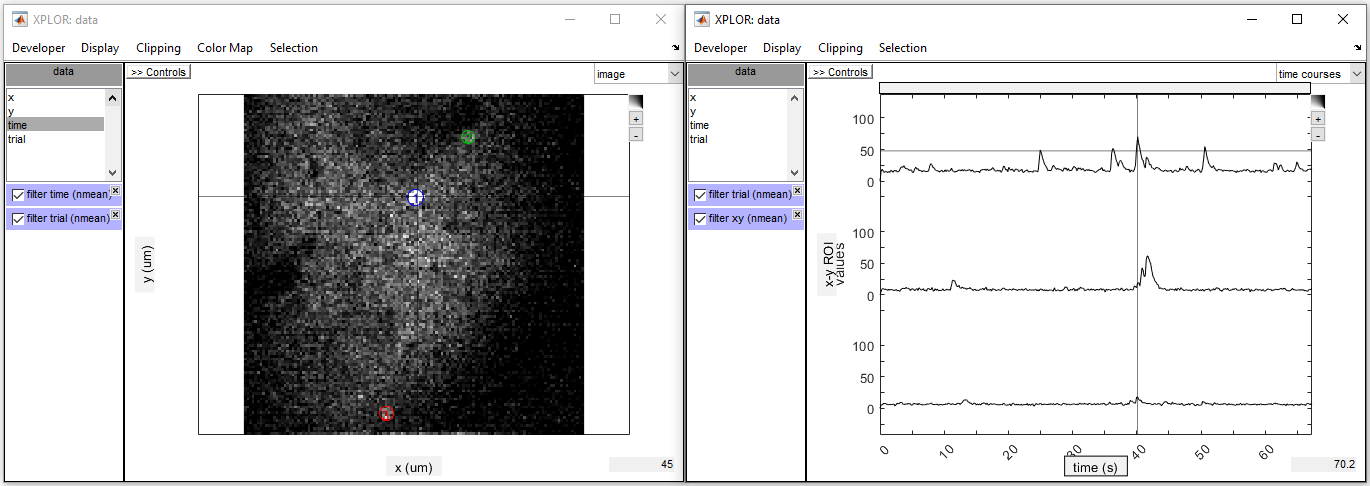

To facilitate the selection of ROIs, it will help to **zoom** in the image. There are 3 ways to zoom in and out:

- click and drag inside the graph with the left button to zoom in; double-click to reset zoom

- use the scroll wheel

- first click the `x` and `y` labels to make zooming sliders appear to the top and to the right of the display; click and drag their edges to control the zoom limits; double-click on the slider to reset zoom

Note also that you can select not only circles but also ellipses: make a click with the mouse left button while you keep the right button pressed: the ellipse main axis is now fixed and you can control its width by continuing to drag.

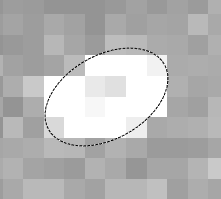

You can also use other drawing shapes:

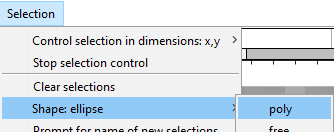

On the time courses side, note that you can color each trace by the color of its corresponding ROI in the context menu that appears when right-clicking the `x-y ROI` dimension label. It can also improve the display to center each signal vertically on its mean value.

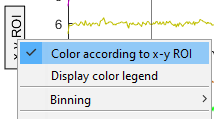

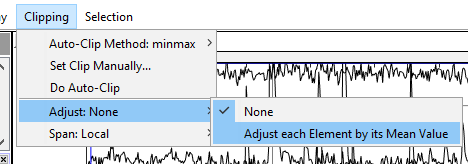

We reached here so far:

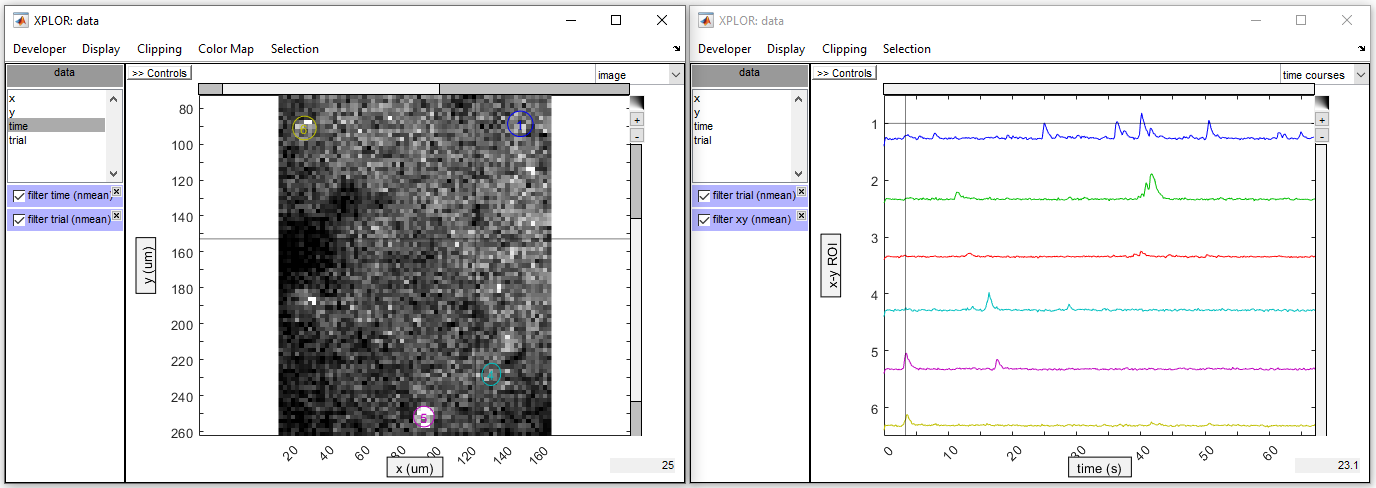

Now the time courses of these regions of interest appear in the other window: all the peaks correspond to periods of time where the neurons are particularly active.

### 2) Temporal ROI

Symetrically temporal selections can be made in the time courses display.

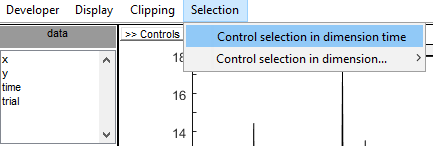

We first trace a large selection (again, by right-click and dragging the mouse inside the graph: result is the blue rectangle below). The image window now shows the average movie image.

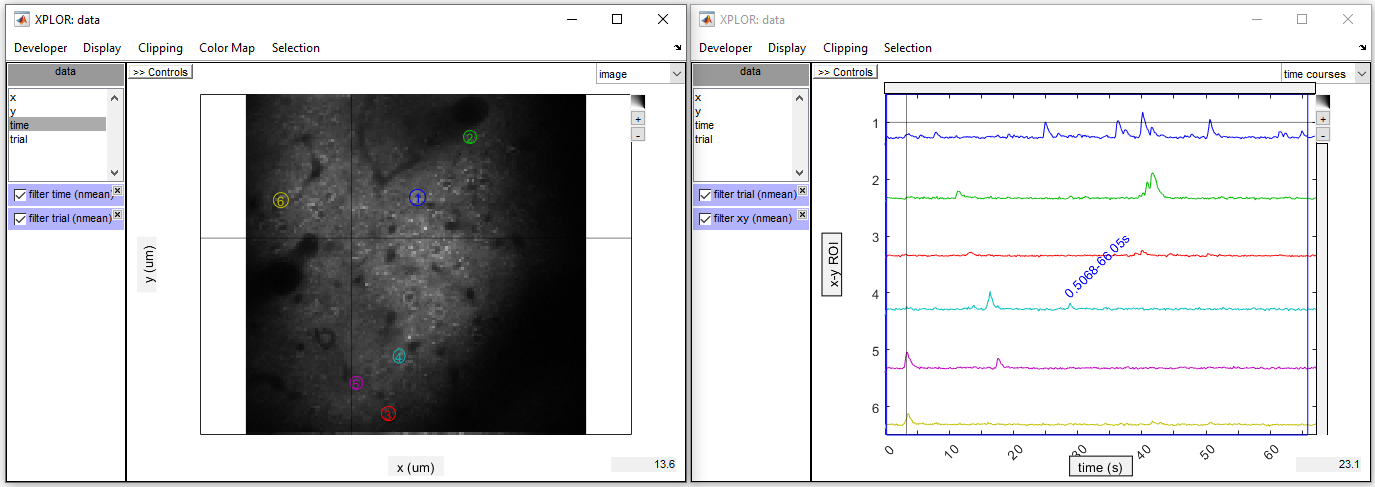

It would be possible to define more than one temporal selections, for example at times of neuronal activity. We then obtain multiple images and a new `time ROI` dimension appears in the first window.

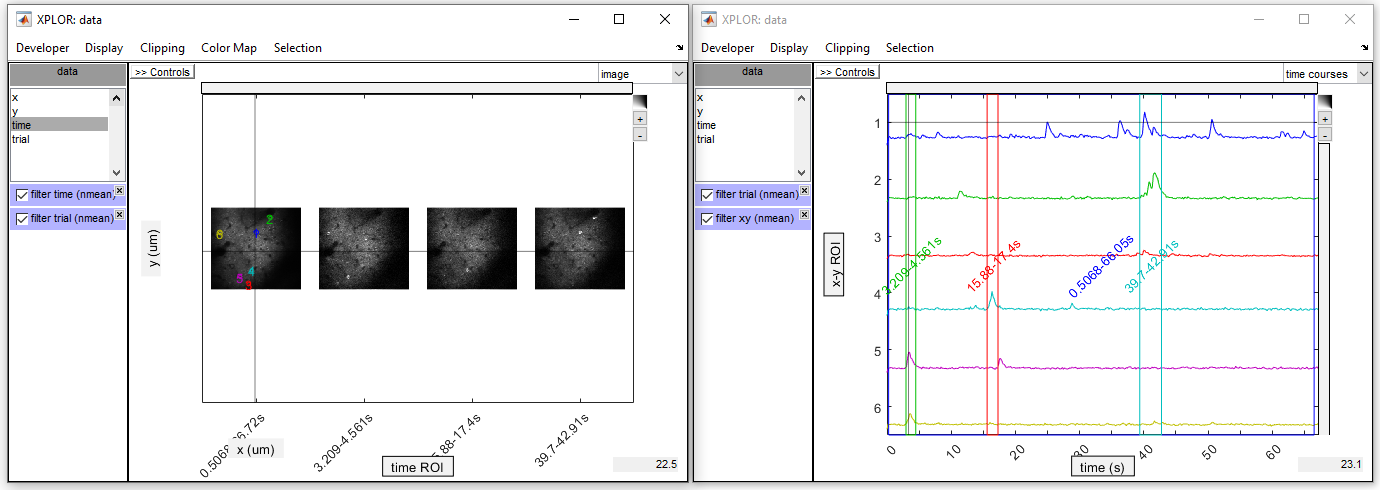

Now notice that the **dimensions can be moved around**, this is a core feature of XPLOR to ease** "looking at data from different perspectives"!**

Click and drag the new `time ROI` dimension label to move it above the graph.

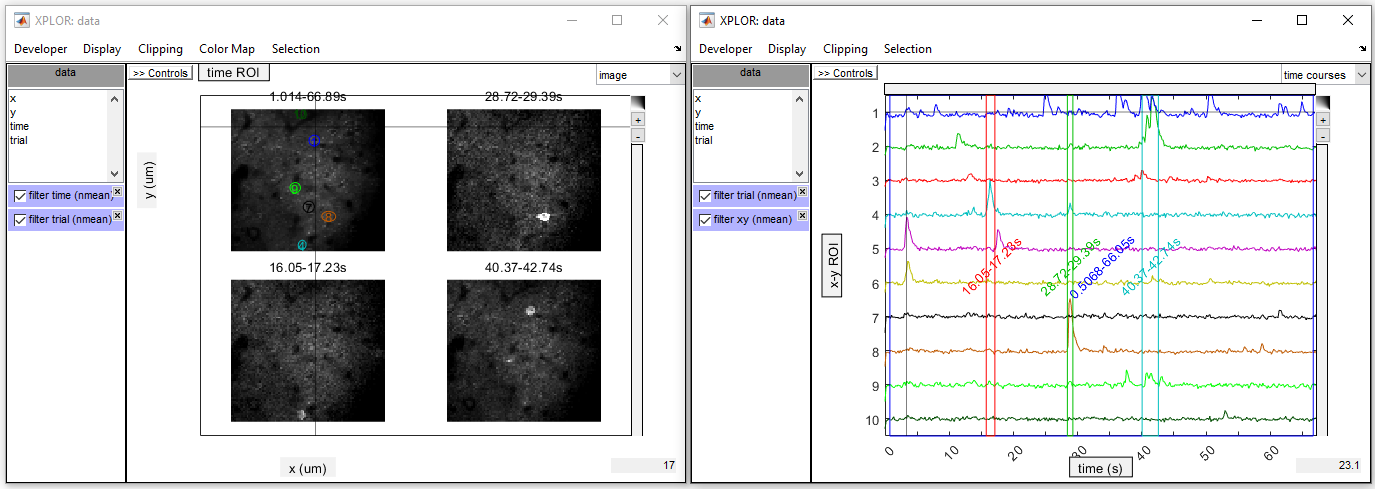

But for now we will remain with a single time selection. For this we can select in the second window:

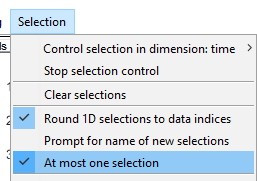.

## More on filters, list filters

Click on a `filter trial` box to see the `trials` filtering list (you can close the `time` filtering list as it will not be used).

If we select the 3 trials, all the image and time courses are "multiplied" by 3! Reorganize the dimensions in theses displays by dragging the dimension labels.

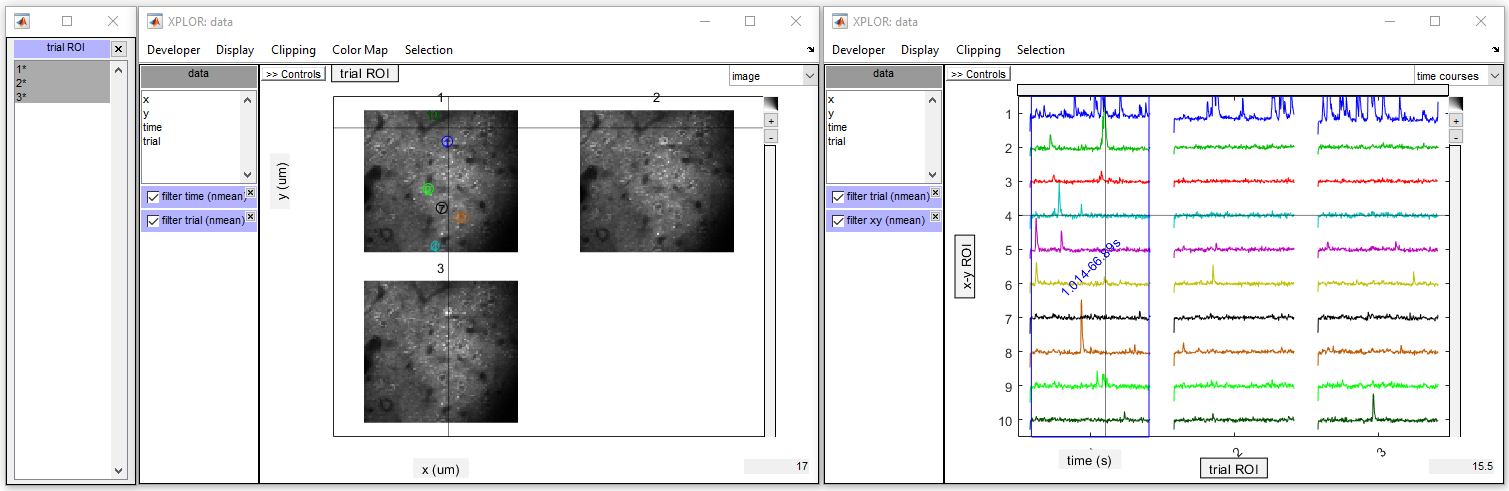

The three images are the average image for each trial, and in the right window we see 30 signals for 10 neurons and 3 trials. 

The first time point of the signals is lower, this is a small acquisition artefact that can be hidden by slighly moving up the lower limit of a temporal zoom: click the `time` dimension label to make the zooming slider appear and drag sligtly its left edge.

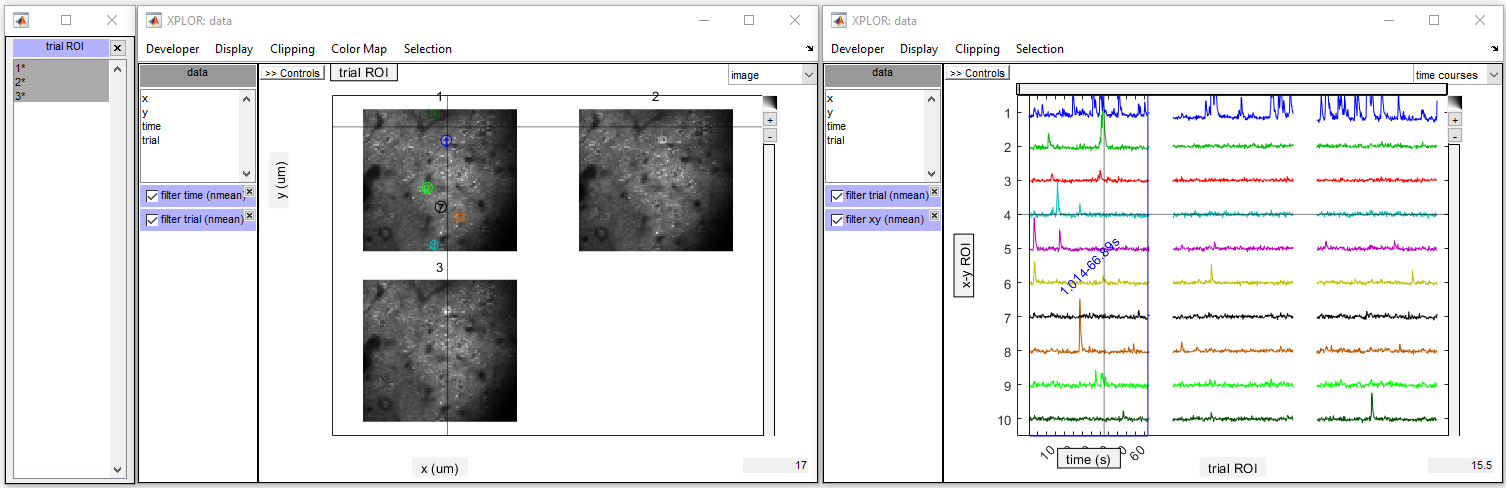

We would prefer to see the global average image rather than one image per trial: right click in the list to tell that so-called "temporary selection" will be groups rather than individuals.

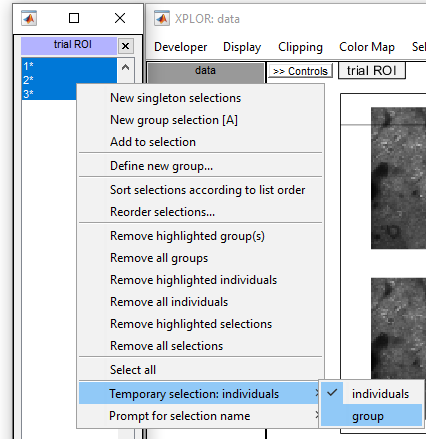

That way we created a "trial ROI", and obtained indeed an average image over the 3 trials. If you want to keep the 3 individual trials in the time courses display, you can remove trial filtering there.

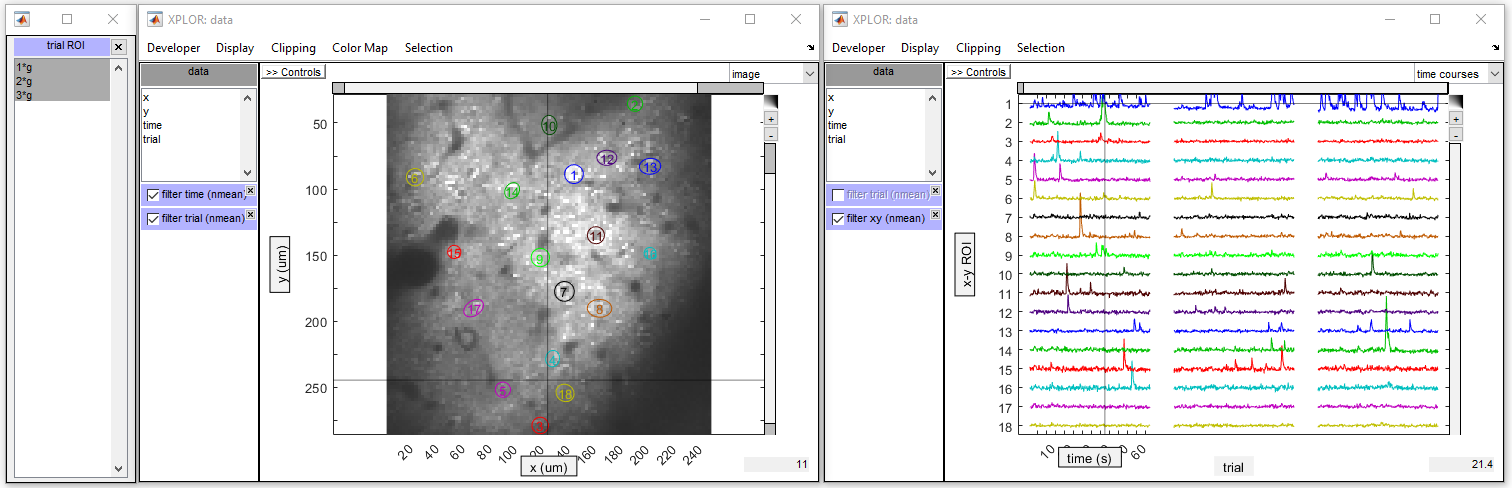

We can also re-define how filters act on ROIs: by default averaging is performed, but we can use different operations, for example `max` to get the maximum value of every pixel over time and trials (we have selected in the menu `Selection > Stop selection control` to hide the neurons ROIs).

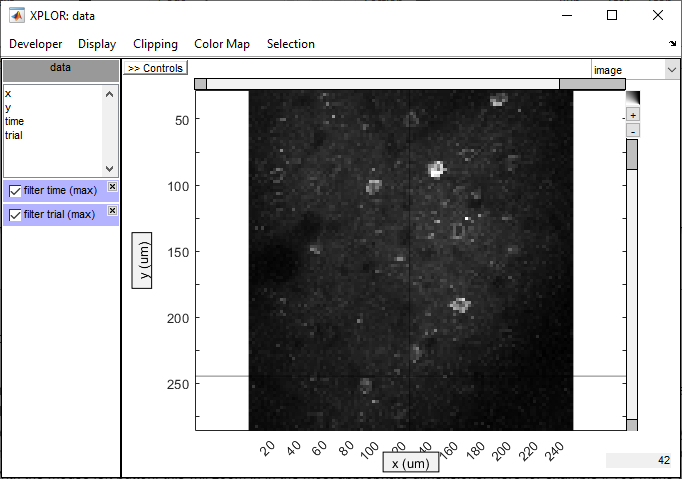

## Save the selection

Do not forget to save the neurons selections so you can load them at a later time!

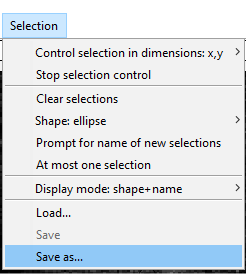

## Get the time courses of the selected neuron ROIs

Wondered about the `Developer` menu? At the present time, there are no dedicated export functions, but by selecting `View object in base space` you can create in Matlab base workspace a variable `V` that allows you accessing all the content of this figure.

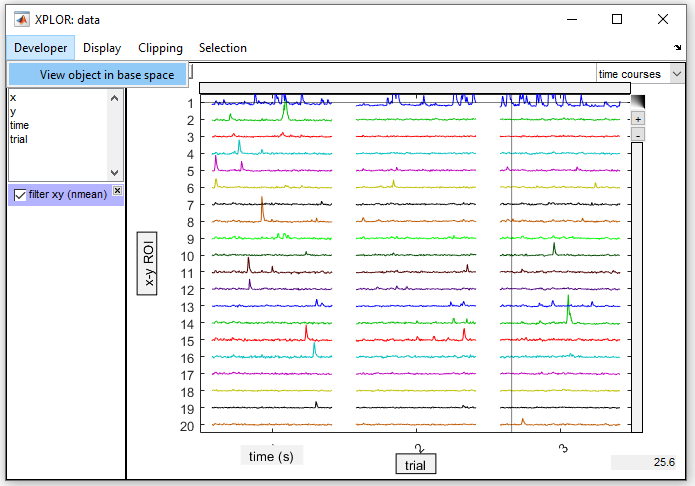

V

ans =     20   400     3


In particular, `V.data` contains the original data (data + header information), and `V.slice` the data displayed in the figure (data + header information), after filters have been applied to the original data.

V.slice
disp(V.slice.header)

ans =   filter with properties:

          selection: [1×20 xplr.selectionnd]
           slicefun: @nmean
        slicefunstr: 'nmean'
               nsel: 20
            indices: {1×20 cell}
           headerin: [1×2 xplr.header]
          headerout: [1×1 xplr.header]
               szin: [128 128]
               ndin: 2
              szout: 20
              ndout: 1
    reductionfactor: 819.2000
            linkkey: 1
      world_operand: [1×1 xplr.worldOperand]
          listening: [1×1 struct]
        idGraphNode: 0.3685


y = V.slice.data;

ans =    |    
   |--- listening : [0x0 Structure]
   |    
   |--------- type : 'ellipse2D'
   |---- listening : [ ]
   |--------- mask : [128x128 Logic array]
   |----------- nd : 2
   |-- idGraphNode : 0.227811
   |---- datasizes : [128 128]
   |------ dataind :  [28x1 Array]
   |------ polygon : [2x50 Array]
   |------- shapes : [1x1 Unknown]

size(y)

The created `y` variable contains the time courses of the 20 selected neurons and for the 3 trials.

We can also obtain the shape definitions and pixel indices of the neuron selections as follows:

V.slicer.filters.obj.F
V.slicer.filters.obj.F.selection(1)